# Solving Heat Equations Using Numerical Methods

Team: Georgia Corbett, Warren Wang

## Finite Element Method (FEM) Discussion

### Convergence Theorem

[insert prose here]

### Applicability to 1-D, 2-D, and 3-D problems

[insert prose here]

### Solving 1-D rod heating example via FEM

We start with a simple second order differential equation to be solved:


$$\frac{\partial^2 u}{\partial x^2} = f(x)$$


with $u(1) = a$ and $u(n) = b$ with some function $f(x)$.

Let us assume for example that $f(x) = x^2 - 3x$. (so the values of $\frac{\partial^2 u}{\partial x^2}}$ should just be 2 so it's easy to check). 


$$\frac{\partial^2 u}{\partial x^2} = x^2 - 3x$$


In order to approximate the second derivative we will use the second derivative midpoint formula:


$$f''(x) \approx \frac{1}{h^2} \cdot [f(x_0 -h) - 2f(x_0) + f(x_0 + h)]$$


which can be found on page 178 of [Richard L. Burden, J. Douglas Faires, Annette M. Burden - Numerical Analysis-Cengage Learning (2015)].

We will coerce this until it looks like it can be a system of equations:


$$f(x_{i-1} - 2f(x_i) + f(x_{i+1}) = h^2 f''(x)$$


Let u(i) = f(x_i) and f(x[i]) = f''(x)


$$u[i-1] - 2u[i] + u[i+1] = h^2f(x[i])$$



$$\pmatrix{1 & -2 & 1} \pmatrix{u[i-1] \cr u[i] \cr u[i+1]} = \pmatrix{h^2 f(x[i])}$$


So we will need to construct matrix $A$, a tridiagonal matrix of the coefficients, and the column vector $b$ of $h^2 * f(x_i)$ values and use MATLAB's linear equation solver to get vector the row vector $x$ in the linear equation $Ax=b$ where $x$ actually holds our approximation values for $u(x)$ that satisfies the differential equation $\frac{\partial^2 u}{\partial x^2} = f(x)$. 

We choose an arbitrary function for $f(x)$ for demonstration purposes.

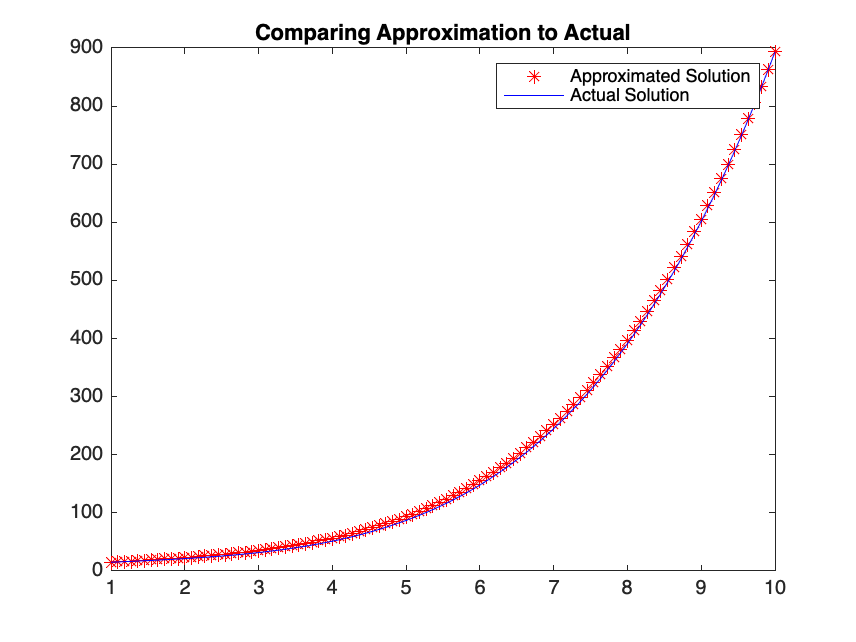

clear;

f = @(x) x^2;
actual_solution = @(x) (x.^4 ./ 12) + 5.*x + 10; % u(x)

N = 100; % num discretizations (including endpoints)
domain_bound_start = 1;
domain_bound_end = 10;
h = (domain_bound_end - domain_bound_start) / N;

% boundary conditions
start_condition = actual_solution(domain_bound_start);
end_condition = actual_solution(domain_bound_end);

A = zeros(N, N);
b = zeros(N,1);
b(1) = start_condition;
b(N) = end_condition;

A(1,1) = 1;
A(N,N) = 1;

x = linspace(domain_bound_start, domain_bound_end, N);

for i = 2:N-1
    A(i,i-1) = 1.0;
    A(i,i) = -2.0;
    A(i,i+1) = 1.0;
    b(i) = h^2 * f(x(i));
end

% Solve
u = A\b;

% plot comparing approx against actual to check
fig = figure;
plot(x, u', '*r');
hold on;
plot(x, actual_solution(x), 'b');
legend('Approximated Solution', 'Actual Solution')
title('Comparing Approximation to Actual')
hold off;


% check greatest error
err = zeros(N, 1);
for i = 2:N-1
    err(i) = abs(u(i+1) - 2*u(i) + u(i-1))/h^2 - f(x(i));
end
max_err = max(err)

max_err =      3.012701199622825e-11


Now for the heat transfer for the 1-D rod

Fourier's Law of Heat Conduction Equation


$$Q = -KA \frac{dt}{dx}$$


K (thermal conductivity)

A (cross sectional area)

Q heat flux

steady state => $Q_{in} = Q_{out}$

expect linear relationship of heat gradient

clear;

K = 15; % say for stainless steel
A = 1;  % say for 1x1 m



## Moving onto the Two Dimensional Heat Equation


$$\frac{\partial u}{\partial t} = c^2 \left( \frac{\partial^2 u}{\partial x^2} + \frac{\partial^2 u}{\partial y^2} \right)$$


$u$ is the temperature at coordinate $(x,y)$ at time $t$

$\frac{\partial u}{\partial t}$ is the change in temperature with respect to time, the temperature difference

We will define this as a boundary value problem with some arbitrary boundary conditions:

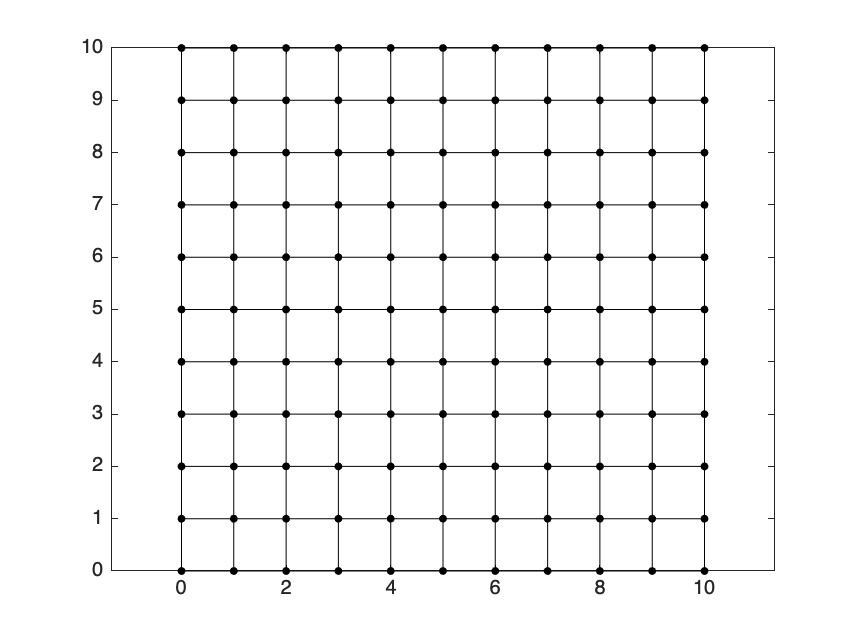

clear;

n = 10; % Size of the domain
numElementsPerSide = 10; % Number of elements per side

% Define the x and y coordinates of the nodes
x = linspace(0, n, numElementsPerSide + 1);
y = linspace(0, n, numElementsPerSide + 1);

% Create a mesh of nodes
[X, Y] = meshgrid(x, y);

% Plot the mesh to visualize
plot(X, Y, 'k.', 'MarkerSize', 10); % Plots the nodes
hold on;
plot(X', Y', 'k'); % Adds vertical lines
plot(X, Y, 'k'); % Adds horizontal lines
hold off;
axis equal;


alpha = 1 % c^2 constant term -- thermal diffusivity (keep 1 for simplicity)

% boundary conditions
u0 = 5; % u(0,0,0)
u1 = 1; % u(0,0,5) ? 